# **S&S Project**

## Semester Project EE-232 

## Design and Implementation of a 5-band Graphic Equalizer 

### Part 1:

The goal of this project is to design a 10-band graphic equalizer and then to implement it - first employing Simulink to check the design and then designing a GUI. 

Matlab can be employed to design the required filters and then Simulink can be used  to implement the graphic equalizer in real time. Most commercial equalizers use either  1/3 octave or 2/3 octave bandpass filters but to keep this from becoming too large we will  employ one octave bandpass filters. Following are the design specifications for the  equalizer:

- Employing Matlab, design 5 different bandpass filters with center frequencies of  63 Hz, 250 Hz, 1000 Hz, 4000 Hz, and 16000 Hz. These center frequencies  correspond to the ISO (International Standards Organization) standard for graphic  equalizer center frequencies.

- The bandwidth of each filter is the frequency difference ∆f = f2 – f1, where f1 and  f2 correspond to the frequencies where the gain is 3 dB less than the maximum  gain at the center frequency. It also is necessary to choose f1 and f2 such that the  center frequency, fc, is equal to the geometric mean of f1 and f2, i.e. fc = (f1f2) 1/2 .  We also have to choose the bandwidth of each filter so that we get a flat frequency  response when all filter gains are equal and added together.

- You can use Butterworth filters; however you are free to choose the order of the  filters. The Matlab help file for the Butterworth filter is the following:                                                                                                                                         ***[B,A] = butter(N,Wn) designs an Nth order lowpass digital Butterworth filter and returns the filter  coefficients in length N+1 vectors B (numerator) and A (denominator). The coefficients are listed  in descending powers of z. The cutoff frequency Wn must be 0.0 < Wn < 1.0, with 1.0 corresponding  to half the sample rate.                                                                                                                                         If Wn is a two-­­element vector, Wn = [W1 W2], butter returns an order 2N bandpass filter with  passband W1 < W < W2.                                                                                                                                                                                     [B,A] = butter(N,Wn,'high') designs a highpass  filter. [B,A] = butter(N,Wn,'low') designs a lowpass  filter. [B,A] = butter(N,Wn,'stop') is a bandstop filter if Wn = [W1 W2]***

- Write a Matlab m-file to compute the set of filter coefficients and plot the  combination (sum) of all filter frequency responses. Note that you can use the  ‘freqz’ command to easily find the frequency response of a filter defined by the  filter coefficient arrays B and A. Your goal is to achieve as flat of a frequency  response as you can when all the frequency response of all filters are added ± 1  dB is a good goal. Remember that the center frequency of each filter must be fixed  to one of the five values given above and the upper and lower cutoff frequencies  f2 & f1 must satisfy fc = (f1f2) 1/2 . Your goal is to find the ∆f value for each filter that achieves a flat frequency response when all filters are  combined with equal weights. [Hint: the filters should all be constant Q, where  Q = fc / (f2 – f1), so once you find the right value for Q all filters should have the  same Q.]                                                                     The simplified 3-band graphic equalizer is shown below, where the filters are in  parallel and each one is followed by a gain (using the Matlab slider gain block).  Your mixer will have 5 filters in parallel.                                                                                                                         We would like to be able to adjust the gain of each band by ± 12 dB. Remember that 6dB corresponds to approximately a factor of 2x, so 12 dB is about 4x. So +12 dB is like multiplying by 4 and -12 dB is like multiplying by ¼.Use these values as  the limits for the slider gain blocks. One final note: The “From Multimedia File” and “To Audio Device” blocks can be  found in the DSP Toolbox

### Part 2:

Design a GUI with the following provisions:

-  A ‘load’ button that can load an audio file of your choice (Suggestion: choose a  file with large frequency range e.g a symphony). 

- Display for the input and output signals. 

- Display for the input and output spectrum. 

- Adjustable gain sliders for the filters. 

- A ‘play’ button that can playback the output file.

% Define center frequencies (Hz)
center_frequencies = [63, 250, 1000, 4000, 16000];

% Define sampling frequency (Fs)
Fs = 44100;

% Optimization parameters
fun = @(params) optimizeFilters(params, center_frequencies, Fs);
x0 = [0.1, 0.5, 0.8, 1.0, 1.2, 1.5];  % Initial guess for Q factors
lb = 0.1 * ones(size(x0));  % Lower bounds for Q factors

% Additional constraints for cutoff frequencies
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = @(params) freqConstraints(params, center_frequencies, Fs);

% Perform optimization
options = optimset('Display', 'iter');
[optimal_Q, fval, exitflag, output] = fmincon(fun, x0, A, b, Aeq, beq, lb, [], nonlcon, options);

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    1.079887e+02    1.810e+04    2.711e-19
    1      14    1.027767e+02    2.201e+04    3.553e-15    5.518e-01
    2      21    1.087696e+02    1.750e+04    4.441e-16    2.317e-01
    3      29    1.048171e+02    2.008e+04    3.553e-15    1.538e-01
    4      36    1.073911e+02    1.819e+04    3.553e-15    1.098e-01
    5      45    1.060325e+02    1.905e+04    7.105e-15    6.782e-02
    6      53    1.054469e+02    1.864e+04    7.105e-15    1.495e-01
    7      62    1.045449e+02    1.927e+04    3.553e-15    3.529e-02
    8      69    1.052066e+02    1.880e+04    1.776e-15    6.748e-02
    9      77    1.046298e+02    1.920e+04    4.441e-16    2.270e-02
   10      84    1.051145e+02    1.886e+04    7.105e-15    4.489e-02
   11      92


% Display optimized parameters
disp('Optimal Q factors:');

Optimal Q factors:


disp(optimal_Q);

    1.0876    0.6130    0.7868    0.7864    0.7866    2.3625



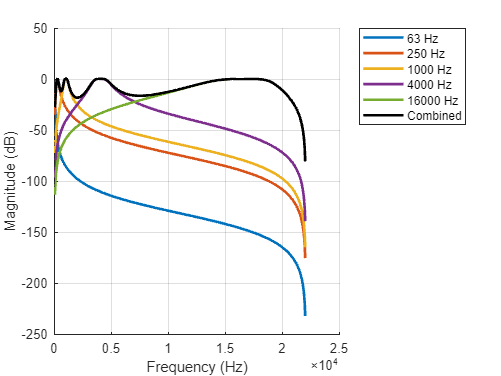


% Design Butterworth filters with optimal Q factors
B = cell(1, length(center_frequencies));
A = cell(1, length(center_frequencies));
for i = 1:length(center_frequencies)
    fc = center_frequencies(i);
    Q = optimal_Q(i);
    f1 = fc / sqrt(2^(1/Q) - 1);
    f2 = fc * sqrt(2^(1/Q) - 1);
    [B{i}, A{i}] = butter(2, [f1, f2]/(Fs/2), 'bandpass');
end

% Plot the frequency response of each filter and the combined filter
figure;
hold on;
H = cell(1, length(center_frequencies));
F = cell(1, length(center_frequencies));
combined_response = zeros(1, 512);
for i = 1:length(center_frequencies)
    [H{i}, F{i}] = freqz(B{i}, A{i}, 512, Fs);
    plot(F{i}, 20*log10(abs(H{i})), 'LineWidth', 2);
    combined_response = combined_response + abs(H{i});
end

% Plot the magnitude response of the combined filter
plot(F{1}, 20*log10(combined_response), 'k', 'LineWidth', 2);

% Add labels and legend
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('63 Hz', '250 Hz', '1000 Hz', '4000 Hz', '16000 Hz', 'Combined', 'Location', 'northeastoutside');
grid on;
hold off;

function error = optimizeFilters(params, center_frequencies, Fs)
    Q = params;
    error = 0;
    
    for i = 1:length(center_frequencies)
        fc = center_frequencies(i);
        Q_i = max(0.1, min(Q(i), 10));  % Ensure Q is within the range [0.1, 10]
        f1 = fc / sqrt(2^(1/Q_i) - 1);
        f2 = fc * sqrt(2^(1/Q_i) - 1);
        [B, A] = butter(2, [f1, f2]/(Fs/2), 'bandpass');
        [H, ~] = freqz(B, A, 512, Fs);
        error = error + norm(abs(H) - 1, 2);  % Minimize the difference from a flat response
    end
end

function [c, ceq] = freqConstraints(params, center_frequencies, Fs)
    Q = params;
    c = [];
    ceq = zeros(1, length(center_frequencies));
    
    for i = 1:length(center_frequencies)
        fc = center_frequencies(i);
        Q_i = max(0.1, min(Q(i), 10));  % Ensure Q is within the range [0.1, 10]
        f1 = fc / sqrt(2^(1/Q_i) - 1);
        f2 = fc * sqrt(2^(1/Q_i) - 1);
        
        % Add constraints for cutoff frequencies
        c = [c, f1, f2];
        ceq(i) = f1 - 0.0001;  % Adjust this value as needed
    end
end
